## **CYKLY SPALOVACÍCH MOTORŮ - SABATE CYKLUS - Seiligerův cyklus**

 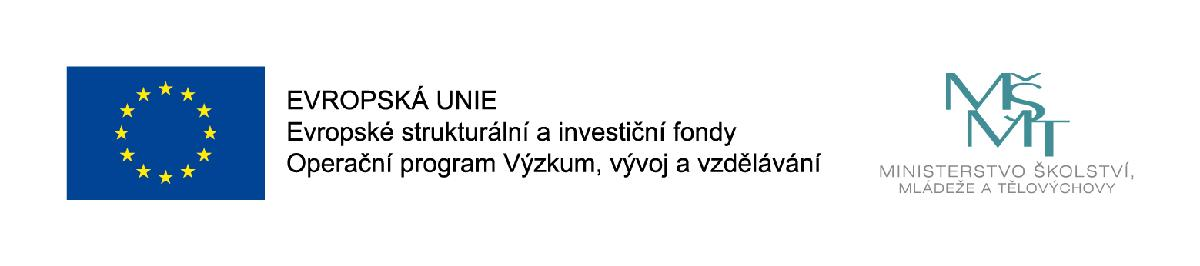

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

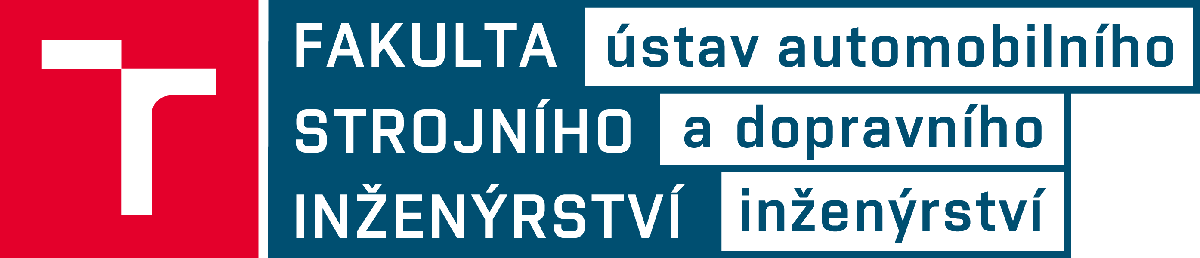

**Zjednodušení zavedená u teoretických cyklů s ideálními plyny**

- Množství a složení plynu v soustavě se nemění (uzavřená soustava)

- Cyklus probíhá s ideálními plyny, fyzikální vlastnosti (*c**p**, **c**v**, κ* aj. ) jsou nezávislé na teplotě

- Hoření nahrazujeme přívodem tepla z okolí

- Výfuk nahrazujeme odvodem tepla do okolí

- Jednotlivé děje nahrazujeme vratnými termodynamickými ději, komprese a expanze bývají adiabatické (nebo technické polytropy

**Seiligerův cyklus** nebo **Sabatův cyklus** je ideální tepelný oběh sestávající z vratných změn. Seiligerův cyklus popisuje práci stroje, kde přívod tepla probíhá smíšeně při poloze pístu v horní úvrati i během expanze a odvod tepla se uskutečňuje ve velmi krátkém čase - bez změny pohybu pístu. Seiligerův cyklus představuje kombinaci Ottova a Dieselova cyklu, které jsou jeho limitními stavy. Jako takový jej lze použít pro oba typy spalovacích motorů při vhodném poměru jeho parametrů.

Vynětové motory nebo-li motory na těžká paliva (nafta, bionafta, oleje) bez svíčky, k zapálení dochází zvýšenou teplotou při kompresi. 

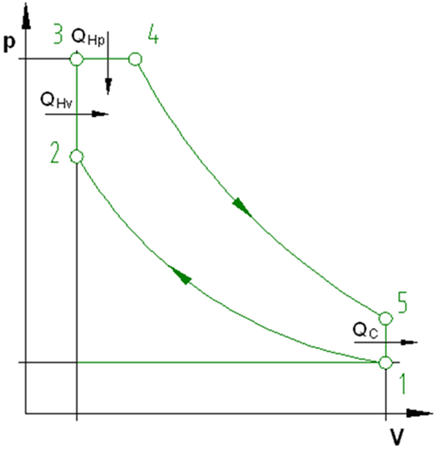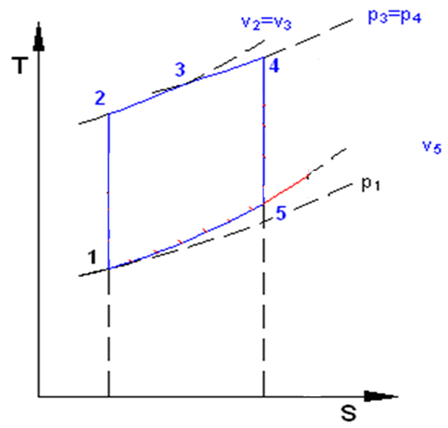

4-dobý motor  0-1-2-3-4-1-0

2-dobý motor  1-2-3-4-1

Zdvihový objem              $V_Z=V_1-V_2$  

Kompresní objem          $V_K=V_2$

Kompresní poměr          $${\epsilon} = \frac{V_1}{V_2}$$

Stupeň plnění                 $${\phi} = \frac{V_4}{V_3}$$

Stupeň zvýšení tlaku      $${\psi} = \frac{p_3}{p_2}$$

**Stupeň izochorického****zvýšení tlaku**

Je to poměr tlaků na počátku a na konci přivádění tepla pracovní látce při konstantním objemu.

U rovnotlakého cyklu probíhá spalování paliva ve válci vzhledem k volnoběžnosti motoru teoreticky při konstantním tlaku. Diesel použil ke vstřiko­vání paliva stlačeného vzduchu. Palivo bylo do válce dopraveno vstřikovacím vzdu­chem (o tlaku 40-80 barů) značně rozprášené. Zdokonalené výrobní metody umož­nily později přímé vstřikování paliva plunžrovým čerpadlem bez vstřikovacího vzdu­chu podstatně vyšším tlakem 200 barů i více. Při rychlém vstřiku paliva a vyšších otáčkách probíhá spalování zčásti přibližně při konstantním objemu, zčásti při konstantním tlaku. Tak vznikl *smíšený *či *kombinovaný cyklus *bezkompresorových motorů. Tento cyklus se nazývá též *Sabatův* podle konstruktéra, který r. 1909 ve Francii sestrojil motor pracující s tímto cyklem. Smíšený cyklus se skládá ze dvou adiabat, ze dvou izochor a jedné izobary.

Účinnost smíšeného cyklu roste podobně jako u výbušného a rovnotlakého cyklu se stoupajícím stupněm komprese a jako u rovnotlakého cyklu s klesajícím a s rostoucím poměrem kompresního a maximálního tlaku.

Smíšený cyklus při  = 1 se změní v rovnotlaký a dále při  *= *1 v cyklus-zážehový. Dosadíme-li tyto hodnoty do vzorce pro účinnost obdržíme výrazy termické účinnosti pro příslušné cykly.

Přívedené a odvedené teplo:


$$${Q_{H1}} = m{c_v}({T_3} - {T_2})$$$
           
$$${Q_{H2}} = m{c_p}({T_3} - {T_2})$$$
                            
$$${Q_C} = m{c_V}({T_1} - {T_4})$$$


Výpočet termické účinnosti:


$$${\eta _t} = 1 - \frac{{\left| {{Q_C}} \right|}}{{{Q_{H1}} + {Q_{H2}}}}$$$


Po úpravách uvedeného výrazu získáme termickou účinnost ve tvaru

# 
$$${\eta _t} = 1 - \frac{{\Psi  \cdot {\phi ^\kappa } - 1}}{{{\varepsilon ^{\kappa  - 1}}[\Psi  - 1 + \kappa \Psi {\kern 1pt} (\phi  - 1){\kern 1pt} ]}}$$$


# 
$$${\eta _t} = f\left( {\kappa ,\;\varepsilon ,\;\phi ,\;\psi} \right)$$$


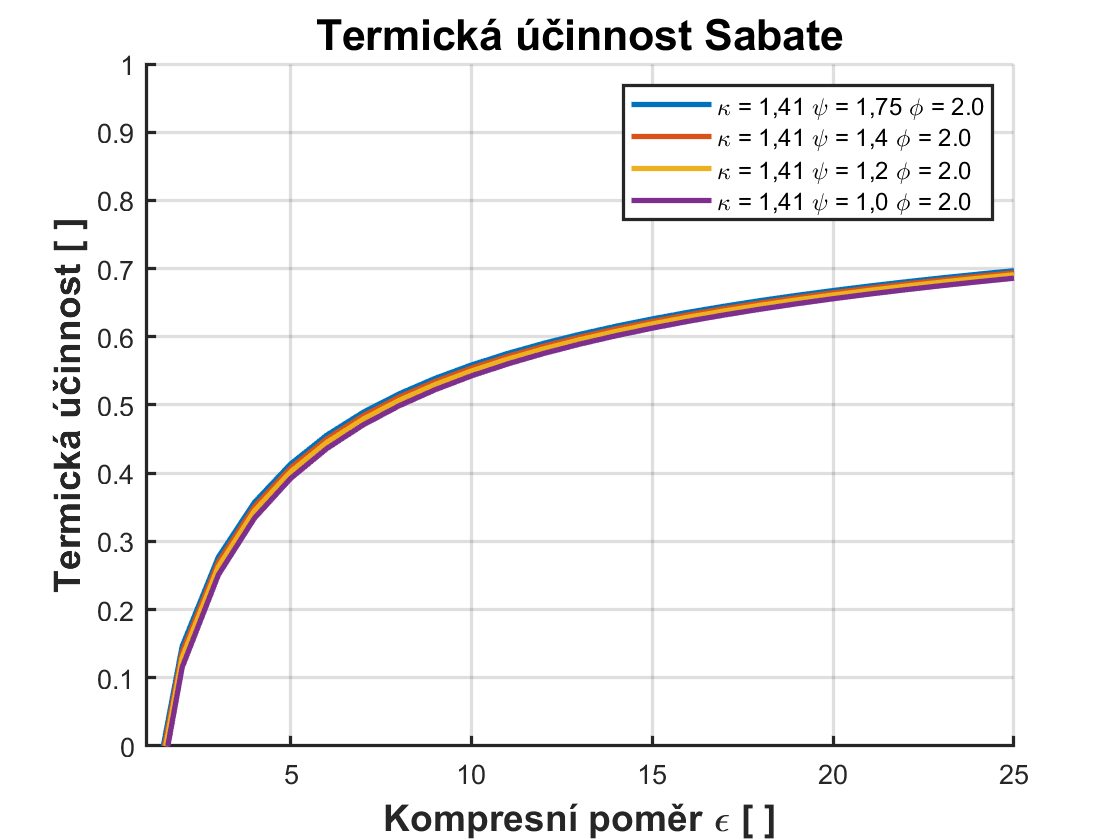

figure;
i = 1;
psi1 = 1.75;
psi2 = 1.4;
psi3 = 1.2;
psi4 = 1.0;

phi1 = 1.0;
phi2 = 1.5;
phi3 = 2.0;
phi4 = 2.5;


eps_v = zeros(1, 25);
eta_t_11 = zeros(1, 25);
eta_t_21 = zeros(1, 25);
eta_t_31 = zeros(1, 25);
eta_t_41 = zeros(1, 25);
for eps=1:1:25
    eps_v(i) = eps;
    eta_t_11(i) = 1-(psi1*phi3^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi1-1+kappaB(2)*psi1*(phi3-1)));
    eta_t_21(i) = 1-(psi2*phi3^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi2-1+kappaB(2)*psi2*(phi3-1)));
    eta_t_31(i) = 1-(psi3*phi3^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi3-1+kappaB(2)*psi3*(phi3-1)));
    eta_t_41(i) = 1-(psi4*phi3^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi4-1+kappaB(2)*psi4*(phi3-1)));
    i = i + 1;
end
title('Termická účinnost Sabate','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Kompresní poměr \epsilon [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Termická účinnost [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1 25]);
ylim([0 1]);
set(gca, 'linewidth',1.2);
hold on;
plot(eps_v,eta_t_11,'-','linewidth',2);
plot(eps_v,eta_t_21,'-','linewidth',2);
plot(eps_v,eta_t_31,'-','linewidth',2);
plot(eps_v,eta_t_41,'-','linewidth',2);
grid on;
legend('\kappa = 1,41 \psi = 1,75 \phi = 2.0','\kappa = 1,41 \psi = 1,4 \phi = 2.0','\kappa = 1,41 \psi = 1,2 \phi = 2.0','\kappa = 1,41 \psi = 1,0 \phi = 2.0');
hold off;

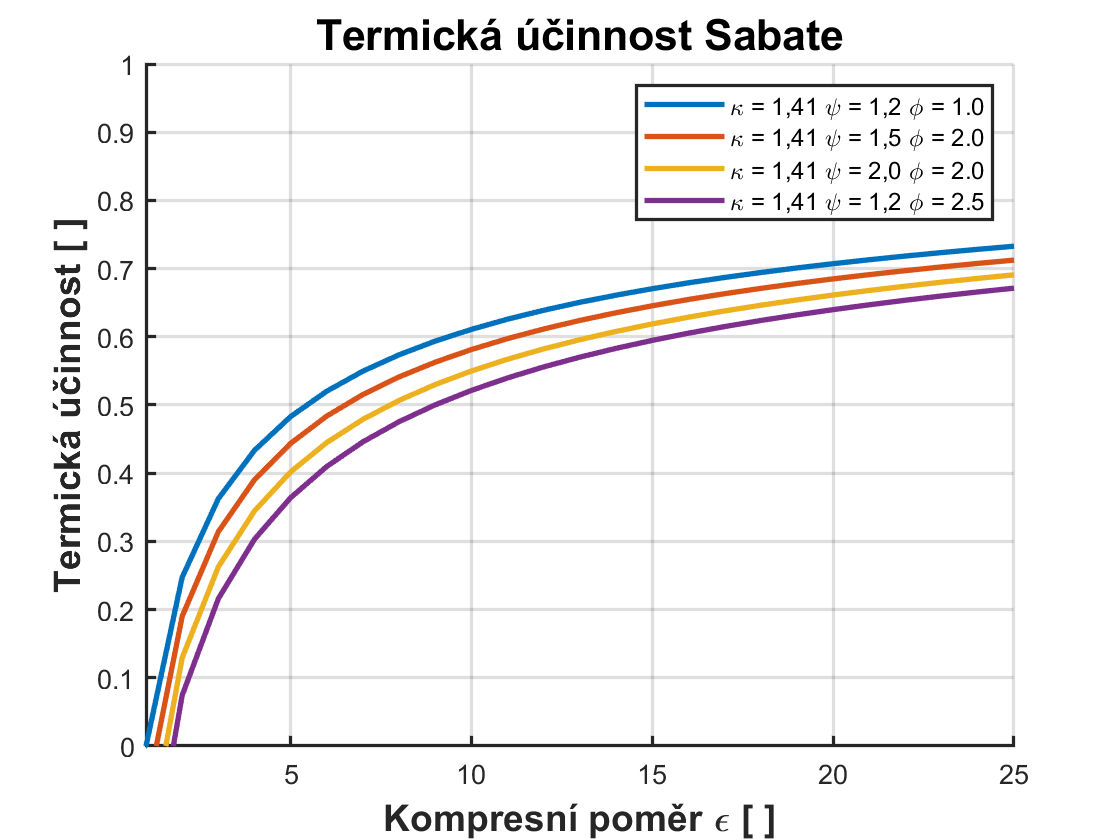

figure;
eps_v = zeros(1, 25);
eta_t_11 = zeros(1, 25);
eta_t_21 = zeros(1, 25);
eta_t_31 = zeros(1, 25);
eta_t_41 = zeros(1, 25);
for eps=1:1:25
    eps_v(i) = eps;
    eta_t_11(i) = 1-(psi3*phi1^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi3-1+kappaB(2)*psi3*(phi1-1)));
    eta_t_21(i) = 1-(psi3*phi2^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi3-1+kappaB(2)*psi3*(phi2-1)));
    eta_t_31(i) = 1-(psi3*phi3^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi3-1+kappaB(2)*psi3*(phi3-1)));
    eta_t_41(i) = 1-(psi3*phi4^kappaB(2)-1)/(eps^(kappaB(2)-1)*(psi3-1+kappaB(2)*psi3*(phi4-1)));
    i = i + 1;
end
title('Termická účinnost Sabate','FontSize', 16 , 'FontName', 'Helvetica','FontWeight','bold');
xlabel('Kompresní poměr \epsilon [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
ylabel('Termická účinnost [ ]','FontSize', 14 , 'FontName', 'Helvetica','FontWeight','bold');
xlim([1 25]);
ylim([0 1]);
set(gca, 'linewidth',1.2);
hold on;
plot(eps_v,eta_t_11,'-','linewidth',2);
plot(eps_v,eta_t_21,'-','linewidth',2);
plot(eps_v,eta_t_31,'-','linewidth',2);
plot(eps_v,eta_t_41,'-','linewidth',2);
grid on;
legend('\kappa = 1,41 \psi = 1,2 \phi = 1.0','\kappa = 1,41 \psi = 1,2 \phi = 1.5','\kappa = 1,41 \psi = 1,2 \phi = 2.0','\kappa = 1,41 \psi = 1,2 \phi = 2.5');
hold off;

# $${\eta _t}$$lze zvyšovat kompresním poměrem

### Příklad

Pracovní látkou v ideálního oběhu čtyřdobého spalovacího motoru s kombinovaným přívodem tepla (naftový motor) se zdvihovým objem 2.0 litru a čtyřmi válci. Tlak nasávaného vzduchu je 981 hPa při teplotý 30 °C. Kompresní poměr je 17, stupeň zvýšení tlaku 2 a stupeň plnění 1,2. Určete stavové veličiny v charakteristických bodech cyklu, přivedené teplo, odvedené teplo, práci cyklu a termickou účinnost.

% Nakreslete p-v a T-s diagram.
Vz = 2.0;   % [kg]
nValcu = 4;
p1hPa= 981; % [hPa]
t1   = 30;  % [C]
eps  = 17;  % [-]
psi  = 2;   %
fi   = 1.5; %

Vlastnosti plynu

r = 287.04;
kappa = 1.41;
cv = 1/(kappa-1) * r;
cp = cv * kappa;

Vk = l2m3(Vz/nValcu)/(eps-1);
V1 = l2m3(Vz/nValcu) + Vk;

T1 = C2K(t1);
p1 = hPa2Pa(p1hPa);
mvzd = (p1 * V1)/(r*T1);
V2 = V1 / eps;
p2 = p1 * eps^kappa;
T2 = p2 * V2 / (mvzd * r);

p3 = p2 * psi;
V3 = V2;
T3 = p3 * V3 / (mvzd * r);
p4 = p3;
V4 = V3 * fi;
T4 = T3 * fi;
p5 = p4*(V4/V1)^kappa;
V5 = V1;
T5 = T1 * p5/p1;
Qh1 = mvzd * cv*(T3-T2);
fprintf('Přivedené teplo při konstantním objemu : %.1f [J]\n',Qh1);

Přivedené teplo při konstantním objemu : 406.1 [J]


Qh2 = mvzd * cp*(T4-T3);
fprintf('Přivedené teplo při konstantním tlaku : %.1f [J]\n',Qh2);

Přivedené teplo při konstantním tlaku : 572.6 [J]


Qh = Qh1 + Qh2;
fprintf('Přivedené teplo  : %.1f [J]\n',Qh);

Přivedené teplo  : 978.8 [J]


Qc = mvzd * cv *(T1-T5);
fprintf('Odvedené teplo   : %.1f [J]\n',Qc);

Odvedené teplo   : -323.2 [J]


Ao = Qh - abs(Qc);
fprintf('Práce cyklu      : %.1f [J]\n',Ao);

Práce cyklu      : 655.6 [J]



etat = Ao / Qh;
fprintf('Termická účinnost: %.3f\n',etat);

Termická účinnost: 0.670


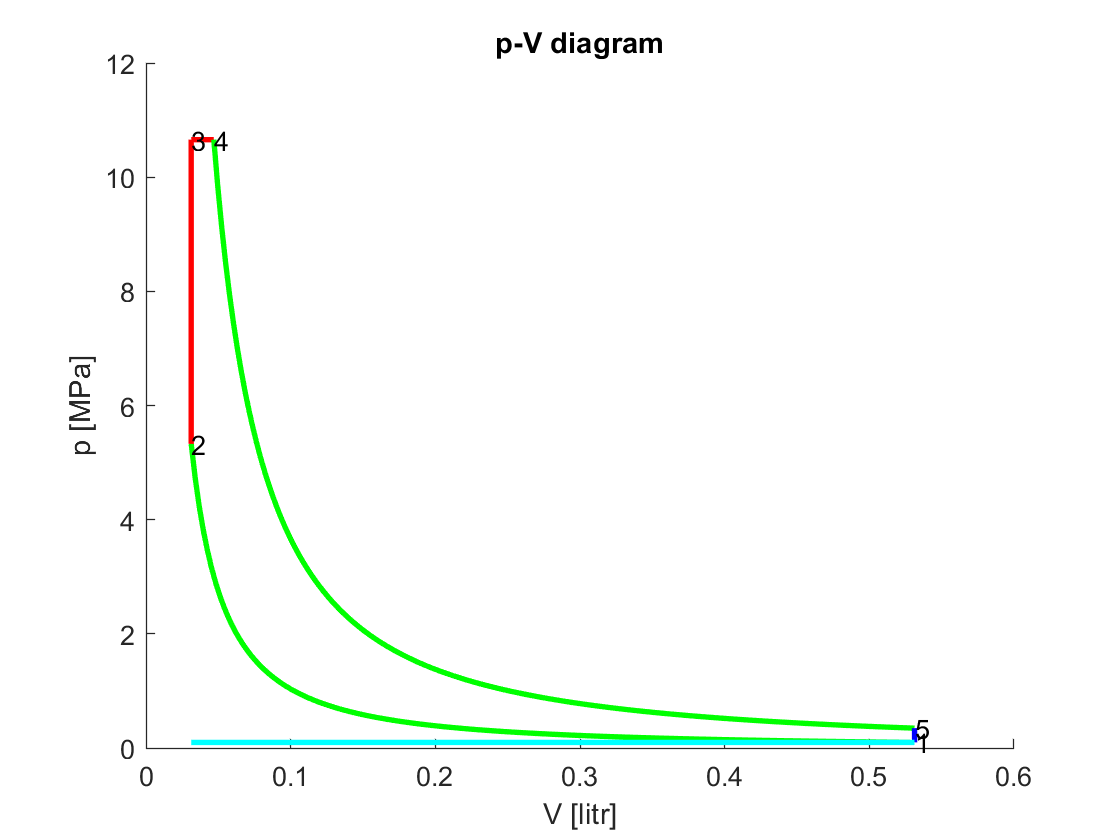


vv1 = linspace(V1,V2,180);
pv1 = zeros([1,180]);
Tv1 = zeros([1,180]);
Sv1 = zeros([1,180]);

for i=2:180
  pv1(i) = p1*V1^kappa/vv1(i)^kappa;
  Tv1(i) = pv1(i) * vv1(i) / (mvzd * r);
  Sv1(i)=mvzd*cp*log(Tv1(i))-mvzd*r*log(pv1(i));
end
pv1(1) = p1;
pv1(180) = p2;
vv1(1) = V1;
vv1(180) = V2;
Tv1(1) = pv1(1) * vv1(1) / (mvzd * r);
Sv1(1)=mvzd*cp*log(Tv1(1))-mvzd*r*log(pv1(1));

pv2 = linspace(p2,p3,180);
vv2 = zeros([1,180]);
Tv2 = zeros([1,180]);
Sv2 = zeros([1,180]);
for i=2:180
  vv2(i)= V2;
  Tv2(i) = pv2(i) * vv2(i) / (mvzd * r);
  Sv2(i)=mvzd*cp*log(Tv2(i))-mvzd*r*log(pv2(i));
end
pv2(1) = p2;
pv2(180) = p3;
vv2(1) = V2;
vv2(180) = V3;
Tv2(1) = pv2(1) * vv2(1) / (mvzd * r);
Sv2(1)=mvzd*cp*log(Tv2(1))-mvzd*r*log(pv2(1));

vv3 = linspace(V3,V4,180);
pv3 = zeros([1,180]);
for i=2:180
  pv3(i)= p3;
  Tv3(i) = pv3(i) * vv3(i) / (mvzd * r);
  Sv3(i)=mvzd*cp*log(Tv3(i))-mvzd*r*log(pv3(i));  
end
pv3(1) = p3;
pv3(180) = p4;
vv3(1) = V3;
vv3(180) = V4;
Tv3(1) = pv3(1) * vv3(1) / (mvzd * r) ;
Sv3(1)=mvzd*cp*log(Tv3(1))-mvzd*r*log(pv3(1));  

vv4 = linspace(V4,V5,180);
pv4 = zeros([1,180]);
for i=2:180
  pv4(i)=p4*V4^kappa/vv4(i)^kappa;
  Tv4(i) = pv4(i) * vv4(i) / (mvzd * r);
  Sv4(i)=mvzd*cp*log(Tv4(i))-mvzd*r*log(pv4(i));    
end
pv4(1) = p4;
pv4(180) = p5;
vv4(1) = V4;
vv4(180) = V5;
Tv4(1) = pv4(1) * vv4(1) / (mvzd * r);
Sv4(1)=mvzd*cp*log(Tv4(1))-mvzd*r*log(pv4(1));    

pv5 = linspace(p5,p1,180);
vv5 = zeros([1,180]);
Tv5 = zeros([1,180]);
Sv5 = zeros([1,180]);
for i=2:180
  vv5(i)= V5;
  Tv5(i) = pv5(i) * vv5(i) / (mvzd * r) ;
  Sv5(i)=mvzd*cp*log(Tv5(i))-mvzd*r*log(pv5(i));
end
pv5(1) = p5;
pv5(180) = p1;
vv5(1) = V5;
vv5(180) = V1;
Tv5(1) = pv5(1) * vv5(1) / (mvzd * r);
Sv5(1)=mvzd*cp*log(Tv5(1))-mvzd*r*log(pv5(1));

vv0 = linspace(V1,V2,180);
pv0 = zeros([1,180]);
for i=2:180
  pv0(i)= p1;
end
pv0(1) = p1;
pv0(180) = p1;
vv0(1) = V1;
vv0(180) = V2;

figure;
% název grafu a popisy os
title('p-V diagram')
xlabel('V [litr]')
ylabel('p [MPa]')   
hold on;
plot(m32l(vv1),Pa2MPa(pv1),'g-','linewidth',2);
plot(m32l(vv2),Pa2MPa(pv2),'r-','linewidth',2);
plot(m32l(vv3),Pa2MPa(pv3),'r-','linewidth',2);
plot(m32l(vv4),Pa2MPa(pv4),'g-','linewidth',2);
plot(m32l(vv5),Pa2MPa(pv5),'b-','linewidth',2);
plot(m32l(vv0),Pa2MPa(pv0),'c-','linewidth',2);
hold off;
% popis bodů diagramu
text(vv1(1)*10^3,(pv1(1)-0.2)/10^6,'1');
text(vv2(1)*10^3,(pv2(1)-0.2)/10^6,'2');
text(vv3(1)*10^3,(pv3(1)+0.2)/10^6,'3');
text(vv4(1)*10^3,(pv4(1)+0.2)/10^6,'4');
text(vv5(1)*10^3,(pv5(1)+0.2)/10^6,'5');

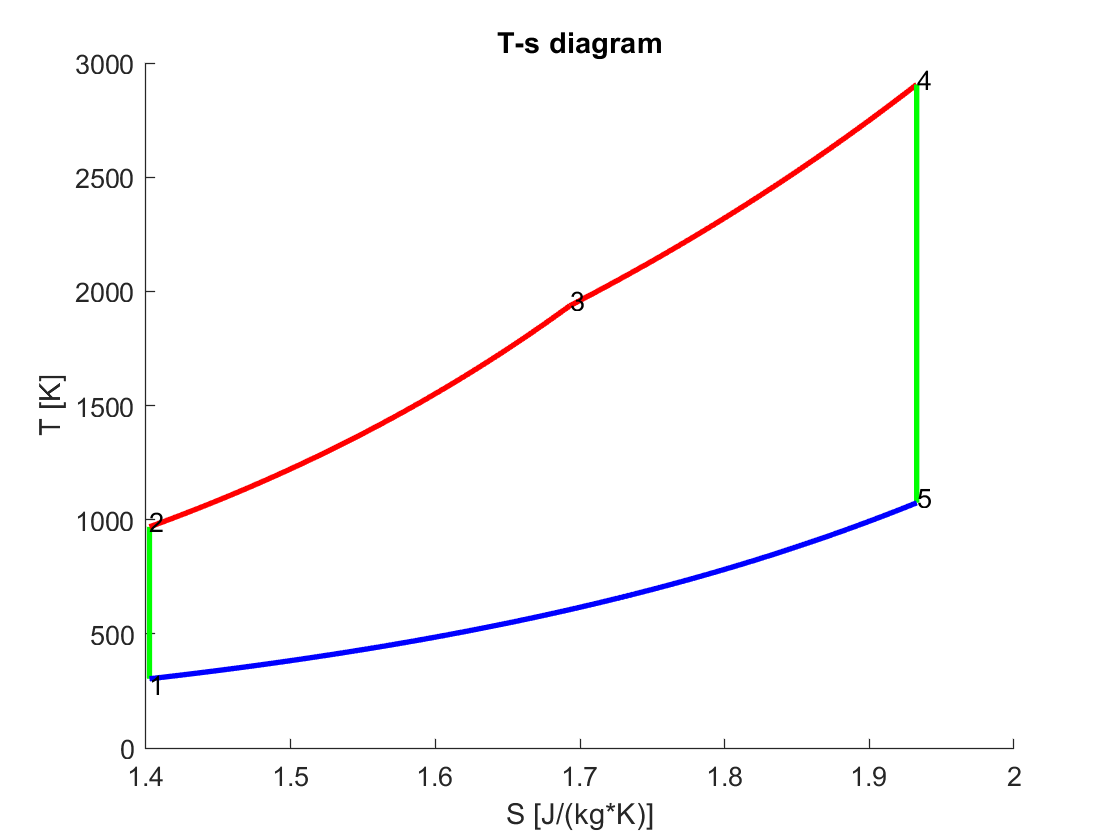


figure;
% název grafu a popisy os
title('T-s diagram')
xlabel('S [J/(kg*K)]')
ylabel('T [K]')                      % ^\circC
hold on;
plot(Sv1,Tv1,'g-','linewidth',2);
plot(Sv2,Tv2,'r-','linewidth',2);
plot(Sv3,Tv3,'r-','linewidth',2);
plot(Sv4,Tv4,'g-','linewidth',2);
plot(Sv5,Tv5,'b-','linewidth',2);
hold off;
% popis bodů diagramu
text(Sv1(1),Tv1(1)-25,'1');
text(Sv2(1),Tv2(1)+25,'2');
text(Sv3(1),Tv3(1)+25,'3');
text(Sv4(1),Tv4(1)+25,'4');
text(Sv5(1),Tv5(1)+25,'5');

### Lokální funkce 

Poissonova konstanta

function [result] = kappaB(atom)
              switch atom
                  case 1  
                    result = 1.67;
                  case 2
                    result = 1.41;
                  case 3  
                    result = 1.3;  
                  otherwise
                    result = 1.3;  
              end     
end

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod litrů

function [l] = m32l(m3)
l = m3 /0.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end